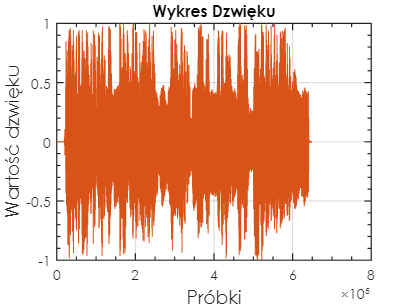

clear; clc; close all;
dzwiek = audioread("random-chinese-sound-effects.mp3");
dzwiekInfo = audioinfo("random-chinese-sound-effects.mp3");
Fs = dzwiekInfo.SampleRate; %czas próbkowania


figure;plot(dzwiek); 
my_figure("Próbki", "Wartość dzwięku", "Wykres Dzwięku");
grid on;

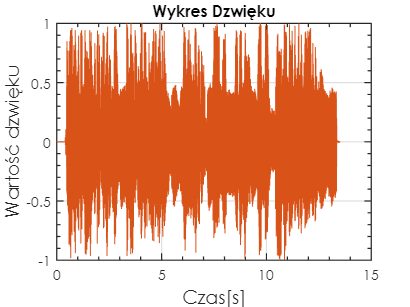


czasFs=1/Fs;

[rowDzw, colDzw] = size(dzwiek);
czasMax=czasFs*rowDzw;
czasDzwiek(:,1) = linspace(0, czasMax, rowDzw);

figure; plot(czasDzwiek ,dzwiek); 
my_figure("Czas[s]", "Wartość dzwięku", "Wykres Dzwięku");
grid on;

%-------------------usuwanie 0----------------------------------------

dzwiek0 = find(dzwiek(:,1) > -0.05 & dzwiek(:,1) < 0.05);
dzwiek0Size = size(dzwiek0);

for i =1:dzwiek0Size(1,1)-1
    roznica(i,1) = dzwiek0(i+1,1)-dzwiek0(i,1);
end

roznicaIdxFind = find(roznica>1);
roznicaIdx = roznicaIdxFind(1,1);

dzwiekBez0(:,1) = dzwiek(roznicaIdx+1:end,1);
hold off

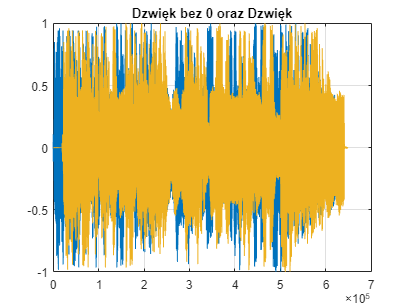

plot(dzwiekBez0)
%my_figure("", "", "Wykres Dzwięku oraz Dzwięku bez 0");
hold on
plot(dzwiek)
hold off
grid on
title("Dzwięk bez 0 oraz Dzwięk");



%-----------------usuwanie nieprawidlowych wartosci z zestawu------------------
load zestawyLaboratoria.mat zestaw1;

zestaw= zestaw1{1,1}(:,:);
zestawMax = maxk(zestaw(:,2),5);
zestawSize = size(zestaw);

for i= 1:zestawSize(1,1)
    if zestaw(i,2) >(zestawMax(1,1)- 300)
        zestaw(i,2) = zestaw(i-1,2);
    else
        zestaw(i,2)= zestaw(i,2);
    end
end

%-----------------------PODOBIEŃSTWO SYGNAŁÓW---------------------------------
%---------------------kowariancja z równania-------------------------------
col2=zestaw(:, 2);
col10=zestaw(:, 10);
[N,~]=size(col2);

m_cov=cov(col2, col10);
covVal = m_cov(1, 2)

covVal = 285.1316

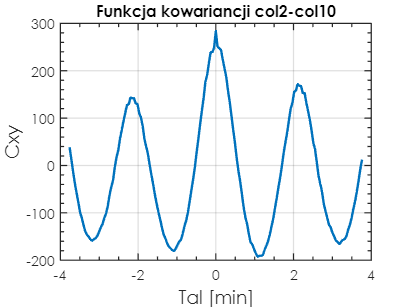


%---------------------kowariancja z funkcji---------------------------
%głównie to zrobiłem dla wykresu a nie dla wartości
[f_cov, lags] = xcov(col2, col10, 'unbiased', N/2);
tal=lags*0.0448;%nie wiedizałem zbytnio czym jest dt, ani jak to wyliczyć
%więc przepisałem z  2022_gaemin_data
figure; plot(tal, f_cov, 'LineWidth', 2); 
my_figure('Tal [min]', 'Cxy', 'Funkcja kowariancji col2-col10');
grid on;


covValZFunkcji = f_cov(tal==0) %<-wychodzi podobnie

covValZFunkcji = 283.4344


%-------------------------korelacja z równania------------------------

var2 = var(col2);
var10 = var(col10);
std2 = std(col2);
std10 = std(col10);
 
wsp_kor1_1 = m_cov(1,1) / var2;
wsp_kor1_2 = m_cov(1,2) / (std2 * std10);
wsp_kor2_2 = m_cov(2,2) / var10;
 
m_kor_cov = [wsp_kor1_1 wsp_kor1_2; wsp_kor1_2 wsp_kor2_2];

m_kor = corrcoef(col2, col10);

korVal=m_kor(1, 2)

korVal = 0.9566


%-------------------kor z funkcji-------------------------------------------
%głównie to zrobiłem dla wykresu a nie dla wartości

%% 2 - xcorr z odjętymi wartościami średnimi i unormowana
[f_kor_norm, lags] = xcorr(col2 - mean(col2), col10 - mean(col10), 'coef', N/2);
tal=lags*0.0448;
subplot(212)
plot(tal, f_kor_norm, 'LineWidth', 2); 
my_figure('Tal [min]', 'Rxy', 'Unormowana funkcja korelacji V-HR');
grid on;
 
 %% 3 - na podstawie funkcji kowariancji
f_kor_cov = f_cov / (std2 * std10);
 hold on;
plot(tal, f_kor_cov, 'LineWidth', 2); 
my_figure('Tal [min]', 'Rxy', 'Unormowana funkcja korelacji col2-col10');
grid on; legend('xcorr normowana', 'na podst. xcov')

subplot(2,1,2)
xlim([-4 4])
ylim([-1 1])
 
korValZFunkcji = f_kor_norm(tal==0)

korValZFunkcji = 0.9566

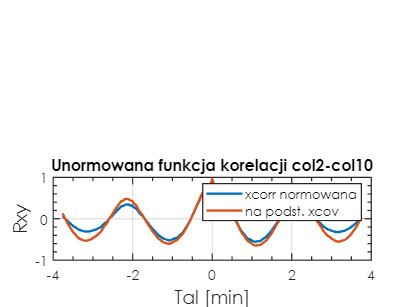

hold off